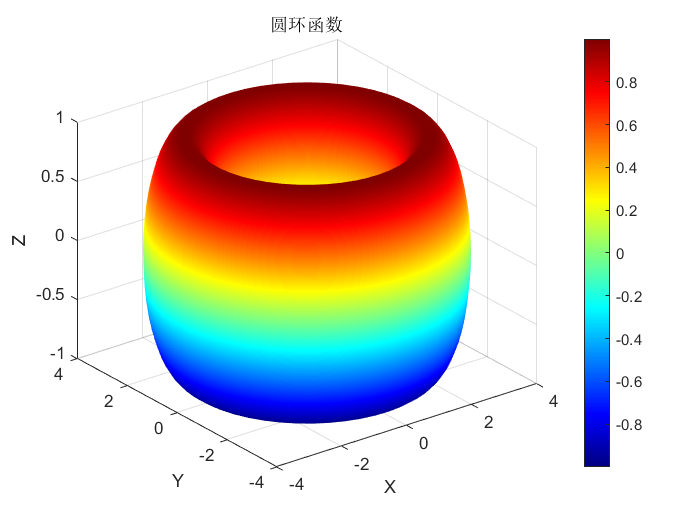

% 定义圆环的内外半径
R = 3; % 外半径
r = 1; % 内半径（环的宽度由这个参数和后续计算中的cos(θ)决定）

% 生成参数θ和φ的网格
[theta, phi] = meshgrid(linspace(0, 2*pi, 50), linspace(0, 2*pi, 50));

% 计算x, y, z坐标
x = (R + r * cos(theta)) .* cos(phi);
y = (R + r * cos(theta)) .* sin(phi);
z = r * sin(theta);

% 使用surf函数绘制三维图像
figure;
surf(x, y, z);

% 添加图形标签和标题
xlabel('X');
ylabel('Y');
zlabel('Z');
title('圆环函数');

% 设置图形视角
view(3); % 或者使用其他视角

% 添加光照效果（可选）
shading interp; % 平滑着色
colormap jet;   % 设置颜色映射
colorbar;      % 显示颜色条
lighting gouraud; % Gouraud光照

% 如果需要，可以添加网格线
grid on;